# TUTORIAL: Fitting Multinomial Logistic Regression Models to Behavioural Data Using Dummy Coding in MATLAB

## What is Multinomial Logistic Regression?

In statistical analysis, **regression** models are a way of estimating the relationship between an outcome of interest, the so-called **dependent variable** (or response), and one or more predictors, also known as **independent variables** or covariates. This requires observations $\left(x_i ,y_i \right)$, $i=1,\dots ,n$, of a response $y_i$ paired with predictor values $x_i$, to which a model is then fitted in order to predict $Y$ from $X$ (because these are now random variables, I use capitalised letters to distinguish them from the observations which are samples of these random variables). The most famous example is probably **simple linear regression**, in which the dependent variable is a continuous quantity and a single predictor is used, such as when trying to predict weight from height. The model states that, given the predictor, the response equals a linear function of it plus a random error:


$$Y_i =\beta_0 +\beta_1 x_i +\varepsilon_i$$


where $\varepsilon_i$ is a random error term with zero mean given $x_i$. With this assumption, the linear regression model describes the expected value of Y conditioned on each observation $x_{i\;}$as a simple trend line with an intercept $\beta_0$ and a slope $\beta_1$:


$$\mathrm{E}\left\lbrack Y∣x_i \right\rbrack =\beta_0 +\beta_1 x_i$$


 The central question, which applies to any regression model, is to find the parameter values that fit the data best according to some criterion: for linear regression the sum of squared errors is minimised (least squares). A first extension is to admit multiple predictors $x_1 ,\dots ,x_p$, collected in the vector $\mathbf{x}={\left(x_1 ,\dots ,x_p \right)}^T$, in which case the model becomes:


$$\mathrm{E}\left\lbrack Y∣\mathbf{x}\right\rbrack =\beta_0 +\beta_1 x_1 +\beta_2 x_2 +\ldotp \ldotp \ldotp +\beta_p x_p =\beta_0 +\sum_{j=1}^p \beta_j x_j$$


Sometimes the variable we want to predict is not a continuous quantity like height but a category, i.e. a **nominal variable**. In the simplest case there are only two categories, for instance 'smoker' vs. 'non-smoker' or 'yes' vs. 'no'. A linear model cannot be applied directly to such outcomes, since they are not numbers, and if we coded them as 0 and 1 a linear function of $\mathbf{x}$ would not keep the predicted probability between 0 and 1. The trick at the heart of **logistic regression** is to model the probability $\pi \left(\mathbf{x}\right)=P\left(Y=\textrm{yes}\textrm{∣}\mathbf{x}\right)$ through its **log-odds** (or logit), the logarithm of the **odds** $\pi /\left(1-\pi \right)$, which can take any real value, and to make this quantity a linear function of the predictors:


$$\mathrm{log}\frac{\pi \left(\mathbf{x}\right)}{1-\pi \left(\mathbf{x}\right)}=\beta_0 +\sum_{j=1}^p \beta_j x_j$$


Technically, without going into further detail, the criterion used to optimise the $\beta$ coefficients is no longer the sum of squared errors which must be minimised in linear regression but the likelihood of observations which is maximised.

Finally, when there are more than two categories, a **multinomial logistic regression** is used . Let the outcome $Y$ take values in $\lbrace 1,\dots ,K\rbrace$ and write $\pi_k \left(\mathbf{x}\right)=P\left(Y=k∣\mathbf{x}\right)$, so that $\pi_1 +\cdots +\pi_K =1$. One category, here $K$, is chosen as the reference, and the log-odds of each of the other categories relative to it are modelled, which gives a system of $K-1$ equations. In the case I will be working on here, we look at the probabilities of choosing levers in a 3-armed bandit task. The outcome on a given trial is nominal, e.g. the agent chose lever 1, and since we have $K=3$ possible choices we want to find the parameters of a system of 2 equations which, taking lever 3 as reference, is:


$$\left\lbrace \begin{array}{c}
\mathrm{log}\frac{\pi_1 \left(\mathbf{x}\right)}{\pi_3 \left(\mathbf{x}\right)}=\beta_{1,0} +\sum_{j=1}^p \beta_{1,j} x_j =\eta_1 \\
\mathrm{log}\frac{\pi_2 \left(\mathbf{x}\right)}{\pi_3 \left(\mathbf{x}\right)}=\beta_{2,0} +\sum_{j=1}^p \beta_{2,j} x_j =\eta_2 
\end{array}\right.$$


Here $\beta_{k,j}$ is the coefficient of predictor $j$ in the equation for category $k$ ($j=0$ being the intercept), and $\eta_k$ is the linear predictor of equation $k$. Note that the predictors $x_j$ are the same in both equations: predictors are the same for both equations, it is what we do with them that is different. Once the parameters are fitted, you can work your way back to the estimated probabilities based on two facts. First, the definition of the log-odds gives $\pi_k =\pi_3 e^{\eta_k }$ for $k=1,2$. Second, the probabilities sum to one, so that:


$$\pi_3 \left(1+e^{\eta_1 } +e^{\eta_2 } \right)=\pi_1 +\pi_2 +\pi_3 =1$$


Solving for $\pi_3$ and substituting back, the estimated probability of each action is:


$$\left\lbrace \begin{array}{c}
\pi_1 =\frac{e^{\eta_1 } }{1+e^{\eta_1 } +e^{\eta_2 } }\\
\pi_2 =\frac{e^{\eta_2 } }{1+e^{\eta_1 } +e^{\eta_2 } }\\
\pi_3 =\frac{1}{1+e^{\eta_1 } +e^{\eta_2 } }
\end{array}\right.$$


## Dummy Coding

I've explained how to deal with nominal dependent variables, now comes the turn of nominal independent variables. Here we can't use the previous trick of replacing variables with log-odds since the observations $\mathbf{x}$ which are indeed random samples of X are nonetheless fixed once observed. Instead, what is needed is simply a numerical encoding of the categories.

**Dummy coding** provides one by replacing a nominal predictor with $K-1$ variables, where $K$ is its number of categories. Each dummy variable equals 1 if the data point belongs to a given category and 0 otherwise. The omitted category is the reference (or default), identified by all dummy variables being 0. Other coding schemes exist, for instance effect coding with values 1, 0 and -1, but they change the interpretation of the coefficients and I will not use them. As an example, if we want to predict height based on sex, we introduce a dummy variable $d$ equal to 1 if the subject is female and 0 if male; the model is:


$$Y=\beta_0 +\beta_1 d+\varepsilon$$


The meaning of $\beta_0$ and $\beta_1$ follows directly from the conditional expectation of $Y$. For a male, $d=0$, so that $\beta_0$ is the expected height of a male (estimated by the sample mean height of the males); for a female, $d=1$:


$$E\left\lbrack Y∣d=1\right\rbrack =\beta_0 +\beta_1$$


which means that $\beta_1$is the difference in expected height between females and males. With three categories we would use two dummy variables, and each coefficient would be the difference in expected outcome between that category and the reference category.

## A Small Simulated Dataset

We are now ready to tackle the main objective of this tutorial, which is to fit a multinomial logistic regression to data collected in a **multi-armed bandit task**. These tasks, which are a classic **reinforcement learning** problem commonly used in neuroscience, are made of discrete trials in which subjects have to choose one action among several in the hope of obtaining a reward. Past rewards and choices can be used as predictors in a logistic regression model to determine the impact of these past events on current choices, as in the study of Lau and Glimcher (2005) which used logistic regression to study the choices of monkeys in a two-alternative task and found that the impact of past rewards decayed in an approximately exponential way. This study inspired me to test a more complex multinomial logistic regression on a three-armed bandit task, which proved to be a more difficult challenge than initially expected.

To start with, we shall need data, which will be a simple synthetic collection of 900 trials with recorded choices and rewards. This virtual experiment will consist of blocks of 100 trials during which one of the levers will be rewarded with a 60% probability if selected, while the two others will be rewarded with a probability of 20% each. To generate plausibly realistic choices, we will use a Q-learning model with a learning rate of 0.1, which also serves as the forgetting rate of the values of non-selected levers, paired with a softmax action selection with an inverse temperature of 5. If you do not understand what this all means, all you need to know is that this is a way of generating interesting data.

%% Simulate some behavioural data

rng(1);  % make the example reproducible

trials_per_block = 100;
schedule = repmat([1, 2, 3], 1, 3); % identities of the best lever in each block of trials
n_blocks = length(schedule);
n_trials = n_blocks * trials_per_block;

data = struct('choices', nan(n_trials, 1), 'rewards', nan(n_trials,1)); % one entry per trial

% initialise the Q-learner
Q = zeros(1, 3);
learningRate = 0.1;
inverseTemperature = 5;

for trial = 1 : n_trials
    
    % given trial number, get the current best lever
    block = ceil(trial / trials_per_block);
    best = schedule(block);
    
    % generate a random choice based on current Q-values
    probs = exp(inverseTemperature * Q) ./ sum(exp(inverseTemperature * Q));
    choice = randsample(1:3, 1, true, probs);
    
    % generate a stochastic reward based on the choice
    reward = rand < (choice == best) * 0.6 + (choice ~= best) * 0.2;

    % update Q-values for next step
    Q = (1 - learningRate) * Q; % forgetting step that applies to all levers
    Q(choice) = Q(choice) + learningRate * reward; % learning that applies only to the selected lever    
   
    % store trial observations
    data.choices(trial) = choice;
    data.rewards(trial) = reward;
end


To get an idea of what this data looks like, here is a quick plot of the rates of selection of each lever using 20-trial moving averages. You should see distinct periods in which the three levers dominate in turn for blocks of roughly 100 trials, illustrating how the Q-learning algorithm manages to keep track of the reward schedule.

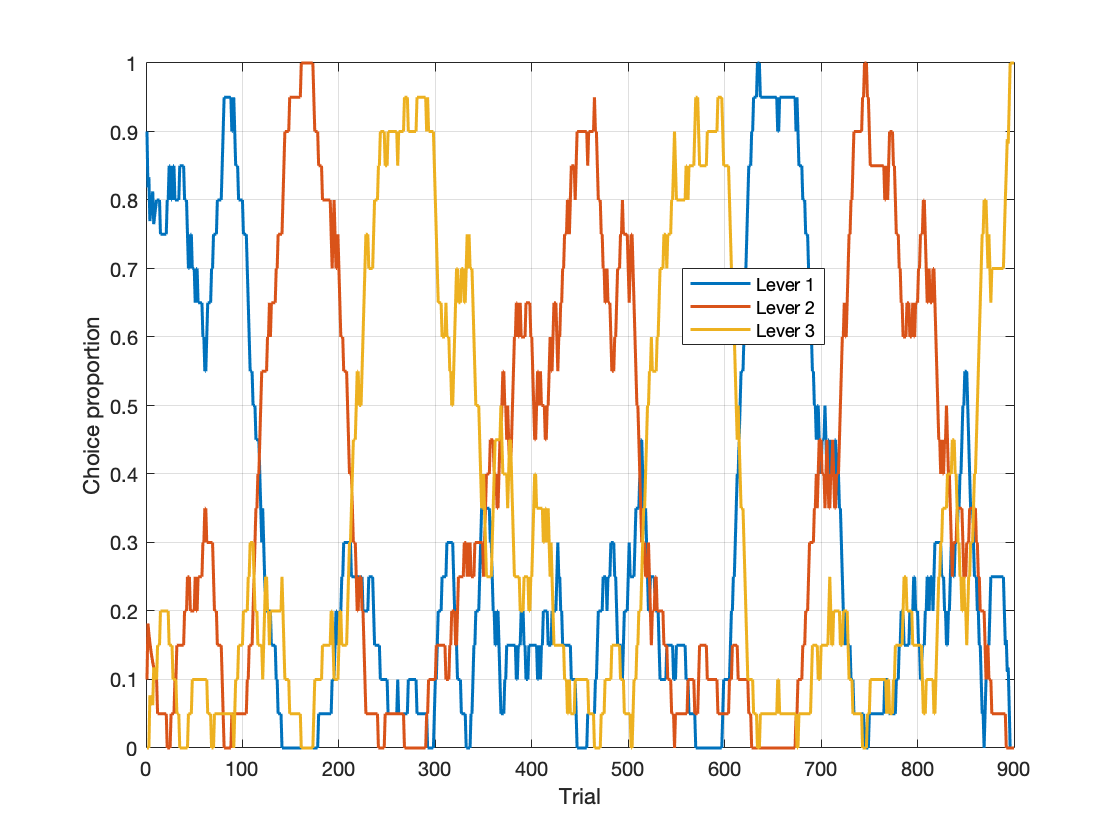

%% running averages of lever selection for quick visualisation

figure()
windowSize = 20;
runningChoiceRate = movmean(data.choices == (1:3), windowSize, 1);

plot(runningChoiceRate, 'LineWidth', 1.5);
xlabel('Trial');
ylabel('Choice proportion');
legend('Lever 1', 'Lever 2', 'Lever 3', 'Location', 'best');

## Constructing the Design Matrix

We now ask whether previous choices and rewards can predict the choice on the current trial. Let $c_t \in \lbrace 1,2,3\rbrace$ be the lever chosen and $r_t \in \lbrace 0,1\rbrace$ the reward obtained on trial $t$. At this point, the design of the regression is really up to you. In my case, I want to use the past $L=10$ trials (the horizon) to predict $c_t$, with five predictors for each lag $\ell =1,\dots ,L$: indicators for having chosen lever 1, having chosen lever 2, having been rewarded on lever 1, having been rewarded on lever 2, and having been rewarded on lever 3, so that there are $p=5L=50$ predictors in total, and the model to be fitted is the system introduced above, with ${\mathbf{x}}_t ={\left(x_{t,1} ,\dots ,x_{t,p} \right)}^T$ as predictors:


$$\log \frac{P\left(c_t =k\textrm{∣}{\mathbf{x}}_t \right)}{P\left(c_t =3\textrm{∣}{\mathbf{x}}_t \right)}=\beta_{k,0} +\sum_{j=1}^p \beta_{k,j} x_{t,j} ,~~k=1,2$$


A few things to note about this design. There is no predictor for having chosen lever 3, which means lever 3 is the reference lever, as above. The last three predictors are choice-reward combinations, 'rewarded on lever $k$' meaning that lever $k$ was chosen and rewarded: predictor 3 is the effect of being rewarded on lever 1 in addition to the effect of selecting lever 1, which is predictor 1. Alternative designs might want to separate these effects, and this choice matters when trying to interpret the final results. The **design matrix** $X$ has one row per observation (trial) and one column per predictor, its entry $\left(t,j\right)$ being $x_{t,j}$, and the response vector $y$ contains the current choices $c_t$. Each past trial in the horizon therefore contributes five columns to $X$.

horizon = 10;
n_levers = 3;
ref_lever = 3; % reference lever (the dummy coding below assumes lever 3)
non_ref_levers = setdiff(1:n_levers, ref_lever);

n_choice_cols = numel(non_ref_levers);
n_reward_cols = n_levers;

cols_per_lag = n_choice_cols + n_reward_cols;
n_pred = cols_per_lag * horizon;

We can now construct X and y.

% We lose the first 'horizon' trials because there is not enough previous history to construct the predictors.
n_rows = n_trials - horizon;

X = zeros(n_rows, n_pred);
y = zeros(n_rows, 1);

row = 1;

for t = horizon + 1 : n_trials % we go through trials filling in the rows of X and y
    
    % Current choice is the response variable
    y(row) = data.choices(t);
    
    % -------------------------------------------------------------
    % Construct predictors from previous trials
    % -------------------------------------------------------------
    
    for lag = 1 : horizon % we repeat these same steps for each lag trial in turn
        
        % First column belonging to this lag
        lag_offset = (lag-1) * cols_per_lag;
        
        past_choice = data.choices(t-lag);
        past_reward = data.rewards(t-lag);
        
        % ---------------------------------------------------------
        % Previous choice
        % ---------------------------------------------------------
        
        % Lever 3 is the reference category, so it does not get
        % its own dummy variable.
        if past_choice == 1
            X(row, lag_offset + 1) = 1;
        elseif past_choice == 2
            X(row, lag_offset + 2) = 1;
        end
        
        % ---------------------------------------------------------
        % Previous rewarded choice
        % ---------------------------------------------------------
        
        % If the previous choice was rewarded, activate the
        % indicator corresponding to the chosen lever.
        if past_reward == 1            
            reward_col = lag_offset + ...
                n_choice_cols + past_choice;            
            X(row, reward_col) = 1;            
        end        
    end    
    row = row + 1;
end

## Fitting the Regression Model

We have now built our design matrix X, which contains the agent's behavioural history, and y, which contains the choice made on the current trial. For horizon = 10, there are 5 predictors per lag × 10 lags = 50 predictors, so X has 50 columns. The first five columns describe the immediately preceding trial (lag 1), the next five describe the trial before that (lag 2), and so on. To fit the multinomial regression model by maximum likelihood we use the built-in mnrfit function. Recent MATLAB releases also provide a newer function, fitmnr, but mnrfit is sufficient for our purposes. By default mnrfit fits a nominal model in which the last category is the reference, which matches our choice of lever 3; the option is stated explicitly below for clarity.

% Fit the multinomial logistic regression
[B, ~, ~] = mnrfit(X, y, 'Model', 'nominal');


The output B contains the fitted coefficients ${\beta^{\textrm{̂}} }_{k,j}$ of the model. It has two columns, the first for the log-odds of choosing lever 1 rather than lever 3 ($k=1$), and the second for the log-odds of lever 2 over lever 3 ($k=2$). It contains 51 rows: the first row is for the intercepts ${\beta^{\textrm{̂}} }_{1,0}$ and ${\beta^{\textrm{̂}} }_{2,0}$, and the remaining 50 for the predictor coefficients, so that $\textrm{B}\left(j+1,k\right)={\beta^{\textrm{̂}} }_{k,j}$. In terms of the design above, the coefficient of predictor type $m\in \lbrace 1,\dots ,5\rbrace$ at lag $\ell$ is found in row $1+5\left(\ell -1\right)+m$ of B. To check the model is working, you can calculate and plot the predicted probabilities of each action using the mnrval function, the fitted B, and the original data X (instead of recycling X, the recommended method is usually to hold out some of the data from the fitting and to use that as a test dataset).

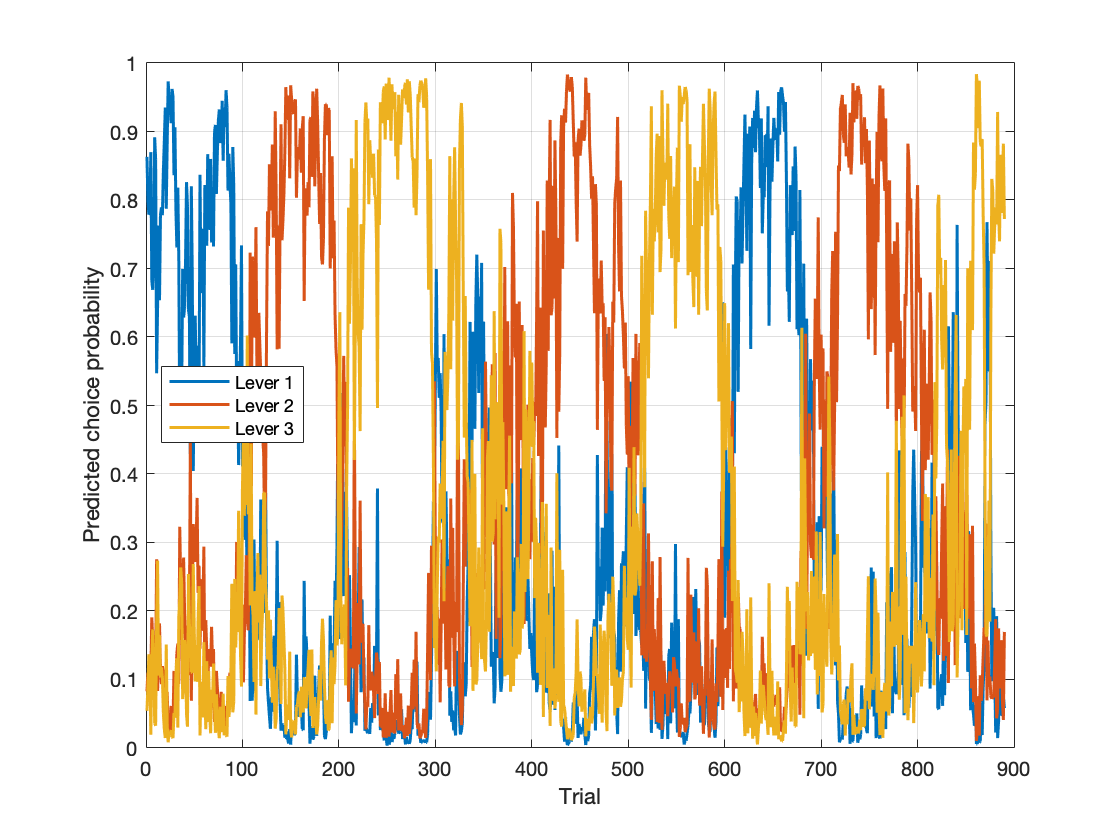

% Evaluate fitted choice probabilities on the observed predictors

P = mnrval(B, X);

figure()
plot(P, 'LineWidth', 1.5);
xlabel('Trial');
ylabel('Predicted choice probability');
legend('Lever 1', 'Lever 2', 'Lever 3', 'Location', 'best');
grid on;

Compared to the running averages we plotted before, the fitted probabilities reproduce broad patterns of the original data. We see dominance of the different levers alternating between blocks, and, unless you have changed the random seed, you should see that the fourth block, in which the agent for some random reason had trouble picking the correct lever 1, is also ambiguous from the fitted model's point of view, thus matching an idiosyncratic feature of the original data.

## A Misguided Attempt to Interpret the Fitted Model

Following the example of Lau and Glimcher, you might want to simply plot some of the fitted coefficients to see how past predictors affect choices. An obvious strategy could be to look at the separate impacts of being rewarded on a lever and of selecting a lever without necessarily being rewarded on the log-odds of that same lever, as measurements of the effects of reinforcement and choice persistence on behaviour. In the case of lever 1 ($k=1$), the coefficients for the predictor 'lever 1 chosen' ($m=1$) are found at rows 2, 7, 12, etc. of B and the coefficients for the predictor 'lever 1 rewarded' ($m=3$) at rows 4, 9, 14, etc. For lever 2 ($k=2$), we are interested in the coefficients of 'lever 2 chosen' ($m=2$; rows 3, 8, 13, ...) and 'lever 2 rewarded' ($m=4$; rows 5, 10, 15, ...).

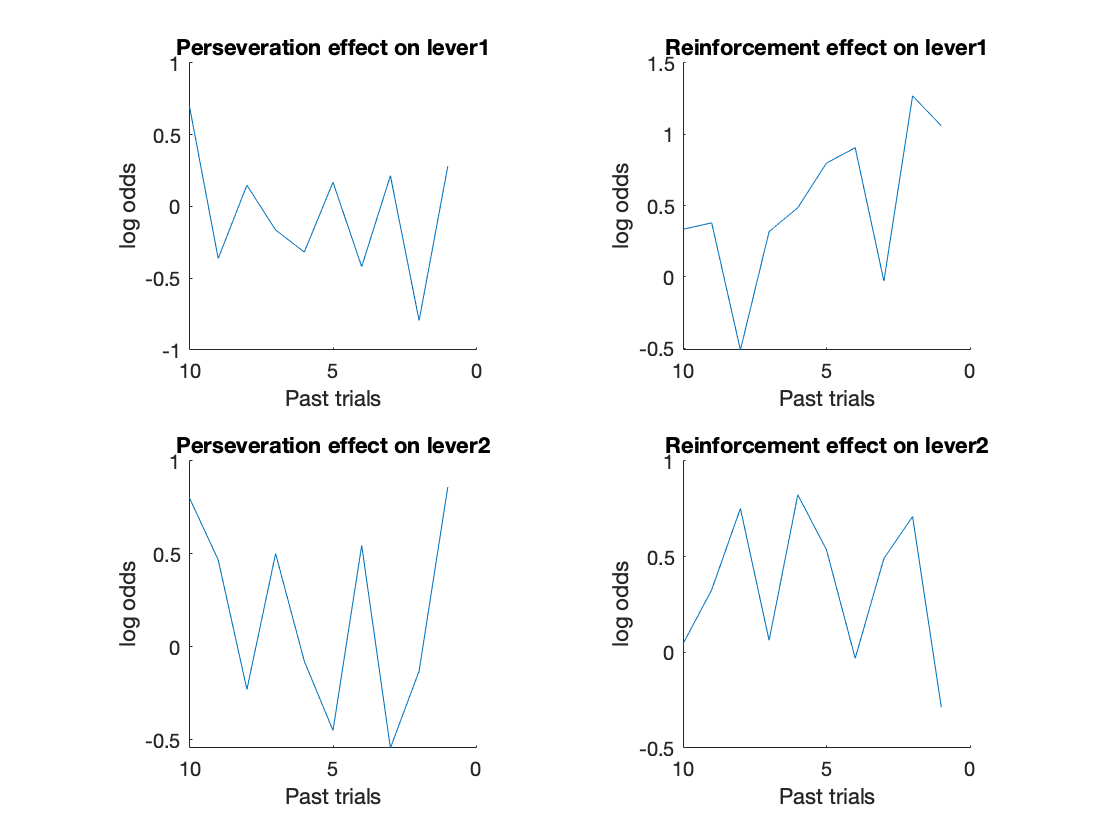

figure()

subplot(2,2,1)
hold on
plot(1 : horizon, B(2 : cols_per_lag : end,1))
title('Perseveration effect on lever1')
xlabel('Past trials')
ylabel('log odds')
set(gca,'XDir', 'reverse')
axis square

subplot(2,2,2)
hold on
plot(1 : horizon, B(4 : cols_per_lag : end,1))
title('Reinforcement effect on lever1')
xlabel('Past trials')
ylabel('log odds')
set(gca,'XDir', 'reverse')
axis square

subplot(2,2,3)
hold on
plot(1 : horizon, B(3 : cols_per_lag : end,2))
title('Perseveration effect on lever2')
xlabel('Past trials')
ylabel('log odds')
set(gca,'XDir', 'reverse')
axis square

subplot(2,2,4)
hold on
plot(1 : horizon, B(5 : cols_per_lag : end,2))
title('Reinforcement effect on lever2')
xlabel('Past trials')
ylabel('log odds')
set(gca,'XDir', 'reverse')
axis square

While the other coefficients have little obvious trend, the coefficients associated with rewarded choices on lever 1 are positive and tend to decrease as we look further into the past, suggesting a positive and decreasing impact of past rewards on selecting lever 1. However, contrary to the original study of Lau and Glimcher, which relied on a simple logistic regression with just two possible outcomes, interpretation of this observation is more delicate. Each coefficient $\beta_{k,j}$ tells us how predictor $j$ affects the log-odds of lever $k$ versus lever 3, rather than how the choice probability $\pi_k$, the quantity we are really interested in, behaves. Indeed, treating $x_j$ as continuous and setting $\beta_{K,j} =0$ for the reference category, differentiating the expressions for the probabilities given earlier yields:


$$\frac{\partial \pi_k }{\partial x_j }=\pi_k \left(\beta_{k,j} -\sum_{l=1}^{K-1} \pi_l \,\beta_{l,j} \right)$$


The effect of $x_j$ on $\pi_k$ therefore depends on the coefficients of all the other non-reference levers and on the current probabilities, and it can even have the opposite sign to $\beta_{k,j}$. (For 0/1 predictors, the analogous quantity is the difference between the predicted probabilities with $x_j =1$ and with $x_j =0$.) This might explain why the other coefficients seem noisy at first glance. To know how the predictors affect choice probabilities, we must take into account the other alternatives, a topic for another time.

**Reference:** Lau, B. and Glimcher, P. W. (2005). Dynamic response-by-response models of matching behavior in rhesus monkeys. Journal of the Experimental Analysis of Behavior, 84, 555-579.